 f= @(x) 0.01*sin(10*x(1))+(0.07*x(1).^2-0.4).^2

f = function_handle with value:
    @(x)0.01*sin(10*x(1))+(0.07*x(1).^2-0.4).^2


epsilon = 0.05;
theta = 0.001;
k = 0.1;
x0 = [-8, -0,5, 1, 8]

x0 =     -8     0     5     1     8


----------------START-------------------


f = function_handle with value:
    @(x)0.01*sin(10*x(1))+(0.07*x(1).^2-0.4).^2


x0 = -8

x1 = -7.9000

alpha = 2

epsilon = 0.0500

theta = 1.0000e-03

a_exp = -4.8000

c_exp = -1.6000

b_exp = 4.8000

i_exp = 7

x = -2.0989

i_lagr = 10

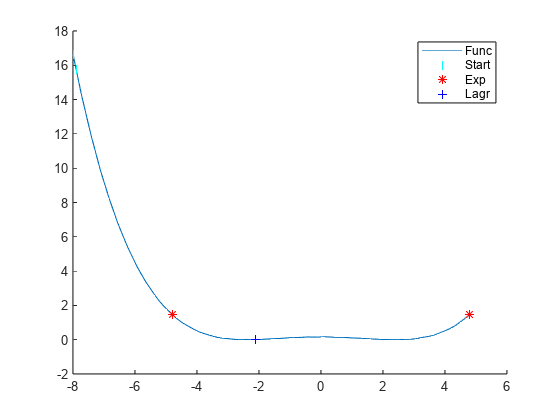

----------------END---------------------


Nmax = 1000;
zad4(f, x0(1), x0(1) + k, 2, epsilon, theta, Nmax)

----------------START-------------------


f = function_handle with value:
    @(x)0.01*sin(10*x(1))+(0.07*x(1).^2-0.4).^2


x0 = 0

x1 = 0.1000

alpha = 2

epsilon = 0.0500

theta = 1.0000e-03

a_exp = -0.4000

c_exp = -0.2000

b_exp = -0.1000

i_exp = 2

x = -0.1771

i_lagr = 4

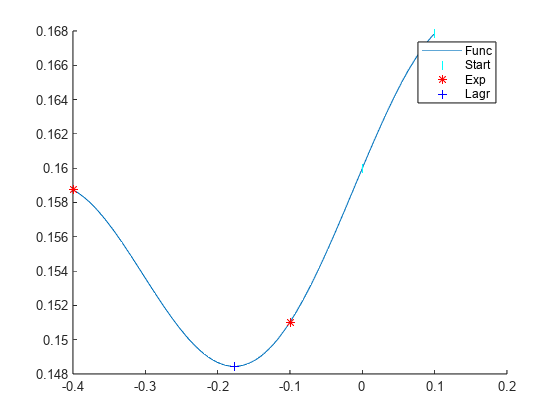

----------------END---------------------


zad4(f, x0(2), x0(2) + k, 2, epsilon, theta, Nmax)

----------------START-------------------


f = function_handle with value:
    @(x)0.01*sin(10*x(1))+(0.07*x(1).^2-0.4).^2


x0 = 5

x1 = 5.1000

alpha = 2

epsilon = 0.0500

theta = 1.0000e-03

a_exp = -1.4000

c_exp = 1.8000

b_exp = 3.4000

i_exp = 6

x = 1.8298

i_lagr = 6

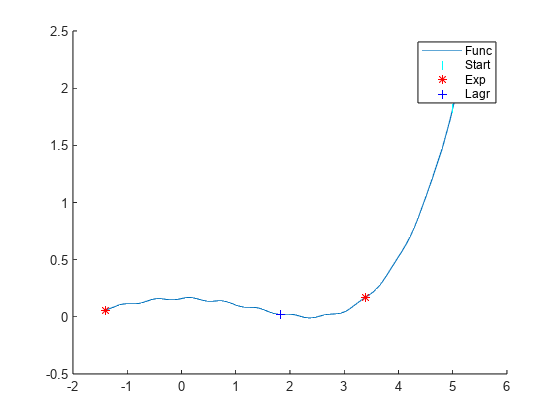

----------------END---------------------


zad4(f, x0(3), x0(3) + k, 2, epsilon, theta, Nmax)

----------------START-------------------


f = function_handle with value:
    @(x)0.01*sin(10*x(1))+(0.07*x(1).^2-0.4).^2


x0 = 1

x1 = 1.1000

alpha = 2

epsilon = 0.0500

theta = 1.0000e-03

a_exp = 1.8000

c_exp = 2.6000

b_exp = 4.2000

i_exp = 5

x = 2.3748

i_lagr = 5

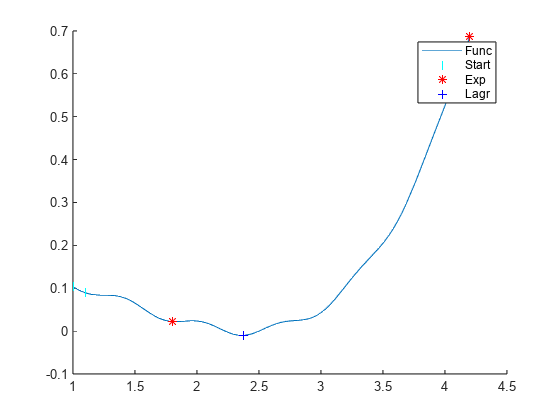

----------------END---------------------


zad4(f, x0(4), x0(4) + k, 2, epsilon, theta, Nmax)


px = [-10 -5 0 5 10];
py = [0.0001 -0.1 0 0.1 -0.0001];
stopien=5

stopien = 5

W = polyfit(px, py, stopien);

f=@(x) (0.001*sin(x/10)).*(0.05*sin(1*x)+W(1)*x.^stopien+W(2)*x.^(stopien-1)+W(3)*x.^(stopien-2)+W(4)*x.^(stopien-3)+W(5)*x.^(stopien-4)+W(6)*x.^(stopien-5))+0.000001*x

f = function_handle with value:
    @(x)(0.001*sin(x/10)).*(0.05*sin(1*x)+W(1)*x.^stopien+W(2)*x.^(stopien-1)+W(3)*x.^(stopien-2)+W(4)*x.^(stopien-3)+W(5)*x.^(stopien-4)+W(6)*x.^(stopien-5))+0.000001*x



[x, i] = lagrange(f, -0.2750, 0.0063, (-0.2750 + 0.0063)/2, 0.05, 0.001, 10000)

x = -0.1004

i = 3

function [] = zad4(f, x0, x1, alpha, epsilon, theta, Nmax)
disp("----------------START-------------------")
f
x0
x1
alpha
epsilon
theta
[a_exp, c_exp, b_exp, i_exp] = expansion_raw(f, x0, x1, alpha, Nmax)
[x, i_lagr] = lagrange(f, a_exp, b_exp, c_exp, epsilon, theta, Nmax)
xmin = min([x0, x1, a_exp, b_exp]);
xmax = max([x0, x1, a_exp, b_exp]);
xlimits = [xmin, xmax];
figure;
hold on;
fplot(f, xlimits);
plot([x0, x1], [f(x0), f(x1)], '|c',...
    [a_exp, b_exp], [f(a_exp), f(b_exp)], '*r',...
    [x], [f(x)], '+b');
legend(["Func", "Start", "Exp", "Lagr"]);
hold off;
disp("----------------END---------------------")
end


function [x, i] = lagrange(f, a, b, c, epsilon, theta, Nmax)
    d = [-inf, inf];
    a = [0, a];
    b = [0, b];
    c = [0, c];
    i = 2;
    while 1
        d(i) = 0.5 * (f(a(i)) * (c(i).^2 - b(i).^2) + f(c(i)) * (b(i).^2 - a(i).^2) + f(b(i)) * (a(i).^2 - c(i).^2))...
                / (f(a(i)) * (c(i) - b(i)) + f(c(i)) * (b(i) - a(i)) + f(b(i)) * (a(i) - c(i)));

        if a(i) < d(i) && d(i) < c(i)
            if f(d(i)) < f(c(i))
                a(i+1) = a(i);
                c(i+1) = d(i);
                b(i+1) = c(i);
            else
                a(i+1) = d(i);
                c(i+1) = c(i);
                b(i+1) = b(i);
            end
        elseif c(i) < d(i) && d(i) < b(i)
            if f(d(i)) < f(c(i))
                a(i+1) = c(i);
                c(i+1) = d(i);
                b(i+1) = b(i);
            else
                a(i+1) = a(i);
                c(i+1) = c(i);
                b(i+1) = d(i);
            end
        else
            x = inf;
            return;
        end
        if b(i) - a(i) < epsilon || abs(d(i) - d(i-1)) <= theta
            break;
        end
        i = i + 1;
        if i > Nmax
            x = inf;
            return;
        end
        
    end
x = d(i);
end

function [a, c, b, i] = expansion_raw(f, xzero, x1, alpha, Nmax)

x0 = xzero;
i = 0;
if f(x0) == f(x1)
    a = x0;
    b = x1;
    return
end

if f(x1) > f(x0)
    x1 = -1*(x1 - xzero) + xzero;
    if f(x1) == f(-1*(x1 - xzero) + xzero)
        a = -1*(x1 - xzero) + xzero;
        b = x1;
        return
    end
end

x2 = x1;
x1 = x0;
while f(x1) > f(x2)
    if i > Nmax
        a = -inf;
        b = inf;
        return 
    end
    i = i + 1;
    x0 = x1;
    x1 = x2;
    x2 = alpha * (x2 - xzero) + xzero;
end

c = x1;
if x0 < x2
    a = x0;
    b = x2;
    return
end
a = x2;
b = x0;
return;
end